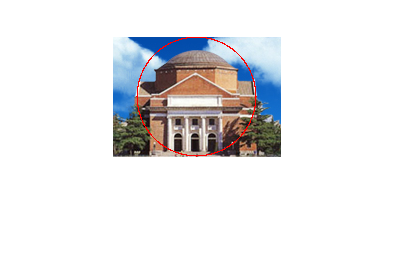

%Chapter1.mlx
%we will 
% a) draw a red circle at the center 
% b) 
load hall.mat;
shape=size(hall_gray);
X=shape(1);
Y=shape(2);
%three color components of the image
r_comp=hall_color(:,:,1);
g_comp=hall_color(:,:,2);
b_comp=hall_color(:,:,3);

% a)
% define the rim of the circle as a region of points(in polar coordinates)
%center, radius and the width of the rim
c=shape/2;
r=min(shape)/2;
dr=0.02*r;
cx=c(1);
cy=c(2);
%discretize the image into x and y coordinates. 
[x,y]=meshgrid(1:X,1:Y);
x=x';
y=y';

rim=(r-dr <=sqrt((x-cx).^2+(y-cy).^2) & (sqrt((x-cx).^2+(y-cy).^2) <=r));

%only pick the red components red
r_comp(rim)=255;
g_comp(rim)=0;
b_comp(rim)=0;

circle_img=cat(3, r_comp,g_comp, b_comp);
imshow(circle_img);

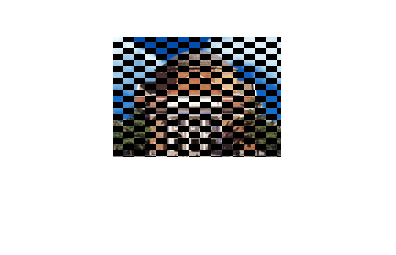



% b)
%number of blocks, block size
n_blk=[20,16];   
blk_sz=round([X/n_blk(1),Y/n_blk(2)]);
X_m=blk_sz(1)*n_blk(1);
Y_m=blk_sz(2)*n_blk(2);

x_period=mod(floor(x/blk_sz(1)),2);
y_period=mod(floor(y/blk_sz(2)),2);
black_zones=(xor(x_period,y_period));

r_comp=hall_color(:,:,1);
g_comp=hall_color(:,:,2);
b_comp=hall_color(:,:,3);

r_comp(black_zones)=0;
g_comp(black_zones)=0;
b_comp(black_zones)=0;

blk_img=cat(3, r_comp,g_comp, b_comp);
imshow(blk_img);